clc, clear
close all

## 三次样条曲线

### 三次曲线表达

三次曲线通常由参数化为 $y=a+b\;x+c\;x^2 +d\;x^3$。

为了方便样条表达，我们可以把它参数化为左右两端点的值和导数。令${\left\lbrack \begin{array}{cccc}
y_0  & y_0^{\prime }  & y_1  & y_1^{\prime } 
\end{array}\right\rbrack }^T$分别表示 $x=0,x=1$两点处的取值和导数，则有


$$\begin{array}{l}
y_0 =a\\
y_0^{\prime } =b\\
y_1 =a+b+c+d\\
y_1^{\prime } =b+2c+3d
\end{array}$$


A = [1 0 0 0
     0 1 0 0
     1 1 1 1
     0 1 2 3];
inv(A)

ans =      1     0     0     0
     0     1     0     0
    -3    -2     3    -1
     2     1    -2     1


即


$$\left\lbrack \begin{array}{c}
a\\
b\\
c\\
d
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
-3 & -2 & 3 & -1\\
2 & 1 & -2 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_0 \\
y_0^{\prime } \\
y_1 \\
y_1^{\prime } 
\end{array}\right\rbrack$$


## 实验

### 轨迹生成

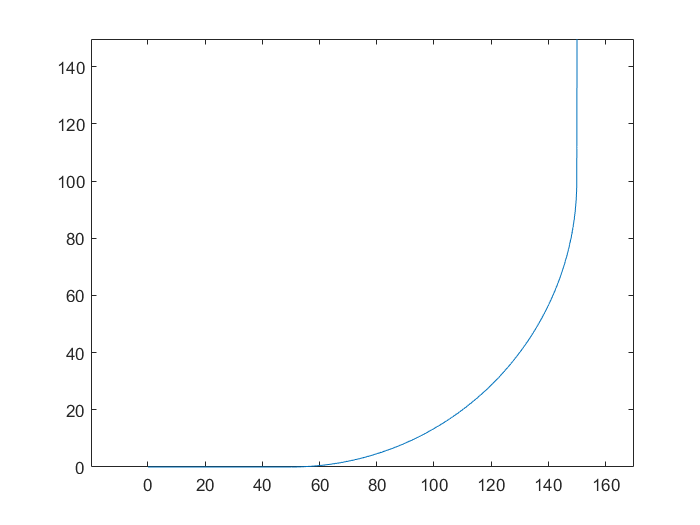

traj1 = GenerateTraj(zeros(500, 1), [0 0 0], 0.1);
traj2 = GenerateTraj(ones(floor(pi/2/0.1*100), 1)* 1/100, traj1(end, :), 0.1);
traj3 = GenerateTraj(ones(500, 1)* 0/100, traj2(end, :), 0.1);
traj = [traj1; traj2; traj3];

plot(traj(:, 1), traj(:, 2))
axis equal

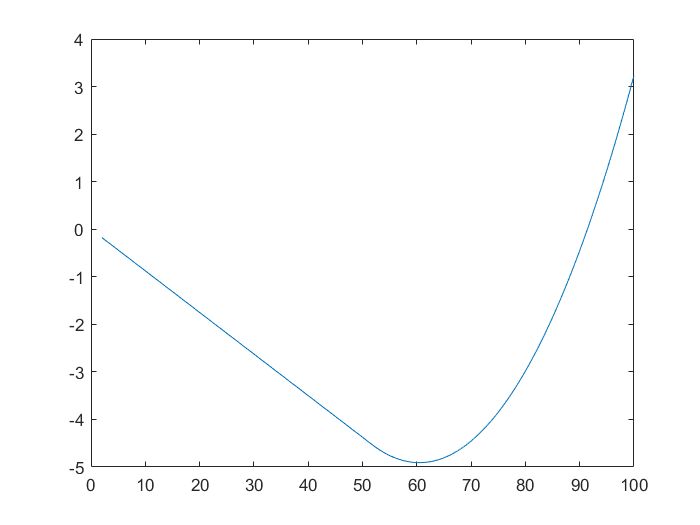


t_local = GetLocal(traj, [-2, 0, deg2rad(-5)]);
plot(t_local(:, 1), t_local(:, 2), '-')

### 3次函数拟合

p_poly = polyfit(t_local(:, 1), t_local(:, 2), 3)

p_poly =     0.0000   -0.0034   -0.0049   -0.4515


e_poly = t_local(:, 2) - polyval(p_poly, t_local(:, 1));
max_error = max(abs(e_poly))

max_error = 0.3003

e2_error = sqrt(mean(e_poly .^ 2))

e2_error = 0.1085

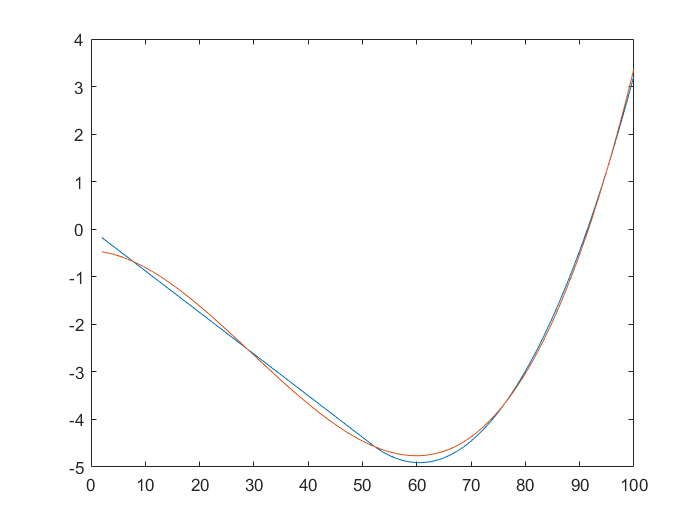

plot(t_local(:, 1), t_local(:, 2), '-', t_local(:, 1), polyval(p_poly, t_local(:, 1)))

### Cubic拟合

cubic = CubicSpline(33, 4);
cubic = cubic.Update(t_local(:, 1), t_local(:, 2));
cubic = cubic.Solve();
t_cubic = cubic.Eval(t_local(:, 1));
e_cubic = t_cubic - t_local(:, 2);
max_c_error = max(abs(e_cubic))

max_c_error = 0.0407

e_c_error = sqrt(mean(e_cubic .^2))

e_c_error = 0.0150

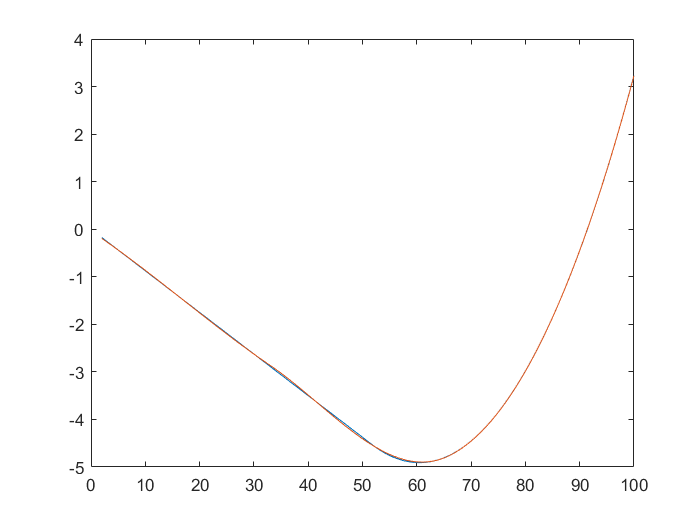

plot(t_local(:, 1), t_local(:, 2), '-', t_local(:, 1), t_cubic)

### Cubic坐标变换

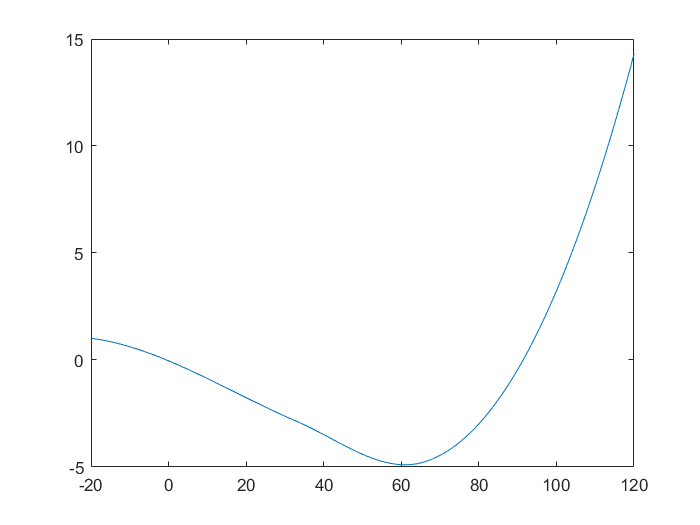

t_x = -20:120;
t_y = cubic.Eval(t_x);
t_test_ori = [t_x', t_y'];
plot(t_x, t_y)

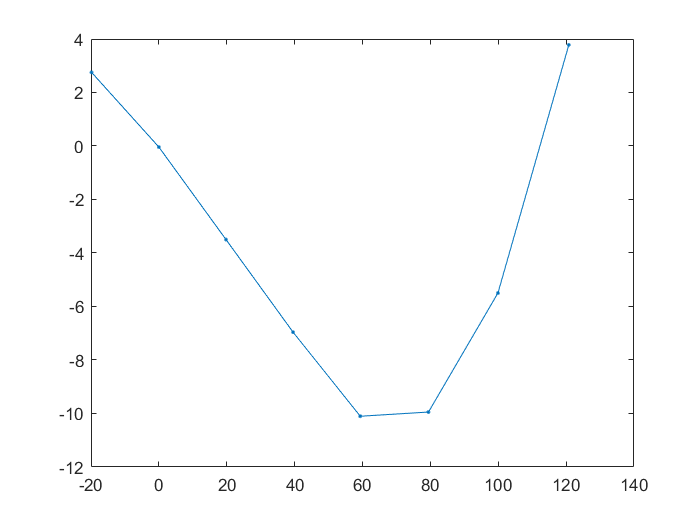

getR = @(t) [cos(t), sin(t); -sin(t), cos(t)];
t_rot = t_test_ori * getR(deg2rad(-5));
t_rot_sample = t_rot(1:20:end, :);
plot(t_rot_sample(:, 1), t_rot_sample(:, 2), '.-')

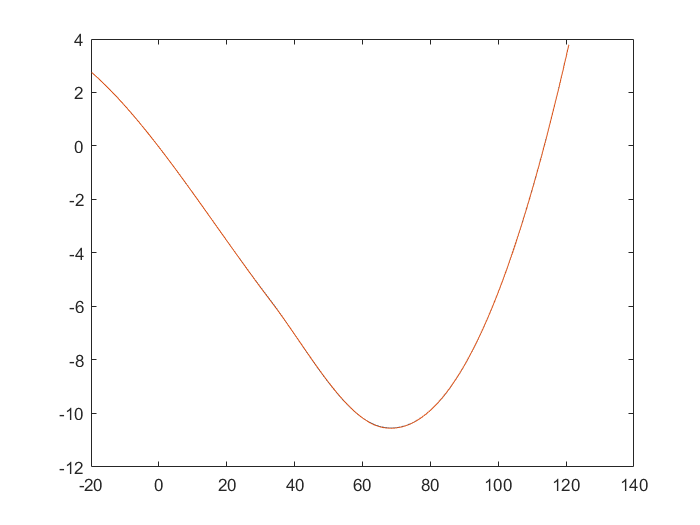

cubic1 = CubicSpline(33, 4);
cubic1 = cubic1.Update(t_rot_sample(:, 1), t_rot_sample(:, 2));
cubic1 = cubic1.Solve();
t_rot_fit = cubic1.Eval(t_rot(:, 1));
plot(t_rot(:, 1), t_rot(:, 2), t_rot(:, 1), t_rot_fit)

max(abs(t_rot(:, 2) - t_rot_fit))

ans = 0.0096

## 函数定义

### 轨迹生成

function [traj] = GenerateTraj(curvatures, traj0, ds)
n = length(curvatures);
traj = zeros(n, 3);
traj(1, :) = traj0;
for ii = 2 : n
    tp = traj(ii - 1, 3);
    traj(ii, 1:2) = traj(ii - 1, 1:2) + [cos(tp), sin(tp)] * ds;
    traj(ii, 3) = tp + curvatures(ii - 1) * ds;
end
end

function [traj_local] = GetLocal(traj, pos)
R = [cos(pos(3)), sin(pos(3)); -sin(pos(3)), cos(pos(3))];
t = (traj(:, 1:2) - pos(1:2)) * R;
I = t(:, 1) > 0 & t(:, 1) < 100 & abs(atan2(t(:, 2), t(:, 1))) < deg2rad(50);
traj_local = t(I, :);
end

function [clamped] = Clamp(x, vmin, vmax)
fmin = x < vmin;
fmax = x > vmax;
clamped = fmin * vmin + fmax * vmax + ~fmin * ~fmax * x;
end